# TRACCIÓN Y COMPRESIÓN AXIAL

Rellena los datos y pulsa Run. Puedes estudiar una varilla uniforme o una barra escalonada con tus propios valores. Las fórmulas y las gráficas se adaptan a la entrada.

Para otro caso modifica solamente Datos. Este documento contiene sus propias funciones de apoyo y se puede compartir como un único archivo .mlx.

## 1. Datos / Input data

Introduce longitudes en m, fuerzas en N, áreas en m² y módulos de elasticidad en Pa. Un valor escalar se aplica a todos los tramos; un vector permite asignar uno a cada tramo.

### Geometría y material

x marca el inicio y el final de cada tramo. F es el área entre dos posiciones consecutivas; E es el módulo de Young. Por ejemplo, x = [0 2] define una varilla de 2 m con un único tramo. No necesitas subdividirla para introducir una carga intermedia.

nombre = "Barra axial";
x = [0 1 2.5 4];
F = [300 200 300] * 1e-6;
E = 210e9;

La notación 1e-6 significa 10⁻⁶: convierte las áreas anteriores de mm² a m². 210e9 significa 210·10⁹ Pa, equivalente a 210 GPa.

### Cargas

Cada fila de P contiene [posición, fuerza]. El signo positivo indica una fuerza hacia la derecha. Cada fila de q contiene [inicio, final, intensidadInicial, intensidadFinal]; sus intensidades se expresan en N/m. Dos intensidades iguales definen una carga uniforme; dos distintas, una carga lineal. Escribe [] si no hay cargas de ese tipo.

P = [1 30000; 4 -10000];
q = [1 2.5 0 10000];

Los espacios separan columnas y el punto y coma separa filas dentro de una matriz. Así, P tiene dos cargas y q tiene una distribución. [] es una matriz vacía; aquí significa ninguna carga.

### Apoyos y holguras

Cada fila de apoyos contiene [posición, desplazamientoImpuesto]. [0 0] fija el extremo en x=0. Para fijar también el extremo derecho añade [x(end) 0] como otra fila. El desplazamiento impuesto se introduce en m.

Deja topes = [] si no hay holgura. Para un tope derecho, una fila [posición, holgura, 1] permite desplazarse hacia la derecha hasta esa holgura; el programa decide si hay contacto. El sentido −1 define un límite hacia la izquierda. Se requiere al menos un apoyo bilateral.

apoyos = [0 0];
topes = [];

### Temperatura

alpha es el coeficiente de dilatación en 1/°C. deltaT es el cambio de temperatura, no la temperatura absoluta. Usa 0 para un problema sin calentamiento. Un vector asigna un cambio constante a cada tramo; una matriz [valorIzquierdo, valorDerecho] por tramo permite una variación lineal.

alpha = 12e-6;
deltaT = 0;

### Resistencia del material

Introduce límites resistentes positivos en Pa y el factor de seguridad requerido. Pueden ser escalares o valores por tramo. Usa Inf para omitir un límite; Inf representa infinito y aquí significa que ese criterio no se comprueba.

limiteTraccion = 250e6;
limiteCompresion = 250e6;
nRequerido = 1.5;

### Presentación

El modo "auto" añade el desglose mecánico y térmico cuando corresponde; "total" muestra solo las cuatro magnitudes totales y "completo" muestra todas las contribuciones. true activa el rayado; false lo desactiva. La presentación física usa kN, MPa, microdeformaciones y mm.

desglose = "auto";
rayado = true;
normalizar = false;
aReferencia = 1;
PReferencia = 1000;
FReferencia = 1e-4;
EReferencia = 210e9;

Deja normalizar = false para trabajar con unidades físicas. Si eliges true, las cuatro referencias positivas establecen las escalas x/a, N/P, σ/(P/F), ε/(P/(EF)) y δ/(Pa/(EF)); no cambian los resultados físicos.

## 2. Signos, símbolos y preparación

El eje x, las fuerzas aplicadas, las reacciones y los desplazamientos son positivos hacia la derecha. N es positivo en tracción y negativo en compresión.

El programa reúne las entradas y añade cortes donde empieza o termina una carga o aparece un apoyo. Esto permite conservar una geometría sencilla sin perder discontinuidades.

datos = struct('nombre', nombre, 'x', x, 'F', F, 'E', E, ...
    'alpha', alpha, 'deltaT', deltaT, 'puntuales', P, ...
    'distribuidas', q, 'apoyos', apoyos, 'topes', topes);
datos.resistencia = struct('limiteTraccion', limiteTraccion, ...
    'limiteCompresion', limiteCompresion, 'nMin', nRequerido);
datos.opciones = struct('desglose', desglose, 'normalizar', normalizar, ...
    'rayado', rayado, 'visible', 'on');
datos.referencias = struct('a', aReferencia, 'P', PReferencia, ...
    'F', FReferencia, 'E', EReferencia);
m = preparar(datos);

struct crea un conjunto de campos con nombre; aquí agrupa tus entradas. El punto accede a un campo: datos.resistencia contiene los límites del material. preparar es una función local que comprueba esos datos y crea las subdivisiones necesarias.

## 3. Equilibrio y compatibilidad

Las fuerzas aplicadas, las cargas distribuidas y las reacciones deben equilibrarse. En cada tramo la fuerza normal cambia según la carga distribuida; los desplazamientos deben ser continuos y respetar los apoyos.


$$\sum_j(P_j+R_j)+\int_{x_0}^{x_f}q(x)\,dx=0$$



$$\frac{dN}{dx}=-q(x),\qquad \varepsilon=\frac{N}{EF}+\alpha\Delta T,\qquad \frac{d\delta}{dx}=\varepsilon$$


Al integrar estas relaciones en un tramo de longitud L se relacionan sus dos desplazamientos extremos. EF/L mide su rigidez axial. La matriz K reúne esas relaciones para toda la barra, y f reúne las contribuciones de carga.


$$\mathbf{k}_i=\frac{E_iF_i}{L_i}\begin{bmatrix}1&-1\\-1&1\end{bmatrix}$$



$$\mathbf{f}_{q,i}=\frac{L_i}{6}\begin{bmatrix}2q_0+q_1\\q_0+2q_1\end{bmatrix},\qquad \mathbf{f}_{T,i}=E_iF_i\alpha_i\frac{\Delta T_0+\Delta T_1}{2}\begin{bmatrix}-1\\1\end{bmatrix}$$


n = numel(m.x); K=sparse(n,n); f=m.P;
for i=1:n-1
    L=m.x(i+1)-m.x(i); EA=m.E(i)*m.F(i); ix=[i i+1];
    K(ix,ix)=K(ix,ix)+(EA/L)*[1 -1;-1 1];
    fq=L/6*[2*m.q(i,1)+m.q(i,2);m.q(i,1)+2*m.q(i,2)];
    ft=EA*m.alpha(i)*mean(m.deltaT(i,:))*[-1;1];
    f(ix)=f(ix)+fq+ft;
end

numel cuenta elementos; aquí cuenta los nodos. sparse crea una matriz que almacena principalmente sus valores no nulos; aquí guarda K. mean calcula una media; aquí obtiene el cambio térmico medio del tramo. for repite instrucciones; aquí recorre todos los tramos.

Se imponen los desplazamientos conocidos y se resuelven los restantes. Las reacciones son el desequilibrio que deben compensar los apoyos. Con un tope se comprueban los estados de contacto y el sentido de su reacción.


$$\mathbf{K}\mathbf{u}=\mathbf{f}+\mathbf{R},\qquad \mathbf{u}_{\mathrm{apoyos}}=\overline{\mathbf{u}}$$


[u, R, activos] = resolverApoyos(m, K, f);
r = struct('u', u, 'R', R, 'contactosActivos', activos);
prototipo = struct('x0', 0, 'L', 0, 'N', zeros(1,3), ...
    'sigma', zeros(1,3), 'epsilon', zeros(1,3), ...
    'delta', zeros(1,4), 'q', zeros(1,2), 'deltaT', zeros(1,2));
r.tramos = repmat(prototipo, n-1, 1);

resolverApoyos es una función local para aplicar restricciones; aquí devuelve los desplazamientos u, las reacciones R y el estado de los topes. zeros crea valores iniciales nulos; aquí prepara los coeficientes. repmat repite una plantilla; aquí reserva un registro por tramo. Esta preparación no impone que el resultado sea cero.

## 4. Fuerza normal: N

Usamos una coordenada local ξ que empieza en cero al comienzo de cada tramo. Si la carga es lineal, q(ξ)=q₀+bξ. Su integración produce una fuerza normal cuadrática; cuando b=0 es lineal y cuando q=0 es constante.


$$q(\xi)=q_0+b\xi,\qquad N(\xi)=N_0-q_0\xi-\frac{b\xi^2}{2}$$


La fuerza inicial N₀ se obtiene de los desplazamientos calculados, incluyendo el alargamiento térmico y la carga repartida:


$$N_0=EF\left(\frac{u_1-u_0}{L}-\alpha\overline{\Delta T}\right)+\frac{L(2q_0+q_1)}{6}$$


for i = 1:n-1
    L = m.x(i+1) - m.x(i);
    EA = m.E(i) * m.F(i);
    q0 = m.q(i,1);
    mq = (m.q(i,2) - q0) / L;
    N0 = EA * ((u(i+1)-u(i))/L - m.alpha(i)*mean(m.deltaT(i,:))) ...
        + L*(2*q0 + m.q(i,2))/6;
    r.tramos(i).x0 = m.x(i);
    r.tramos(i).L = L;
    r.tramos(i).N = [-mq/2 -q0 N0];
    r.tramos(i).q = [mq q0];
end

El vector [-mq/2, -q0, N0] contiene los coeficientes de ξ², ξ y 1. Esta forma permite evaluar la misma ecuación en cualquier sección. EA es el producto E·F; la variable se llama así por la notación habitual del área A, pero aquí el área sigue siendo F.

## 5. Tensión normal: σ

La tensión es la fuerza interna dividida entre el área. Un cambio de sección puede producir un salto de tensión aunque N no cambie. El signo conserva la distinción entre tracción y compresión.


$$\sigma(\xi)=\frac{N(\xi)}{F_i}$$


for i = 1:n-1
    r.tramos(i).sigma = r.tramos(i).N / m.F(i);
end

## 6. Deformación unitaria: ε

La deformación total suma la parte elástica y la térmica. Con temperatura constante la parte térmica es constante; si cambia linealmente, también lo hace su contribución. Un tramo calentado puede deformarse aunque su fuerza normal sea cero.


$$\varepsilon(\xi)=\frac{\sigma(\xi)}{E_i}+\alpha_i\Delta T(\xi)$$


for i = 1:n-1
    T0 = m.deltaT(i,1);
    mT = (m.deltaT(i,2) - T0) / r.tramos(i).L;
    r.tramos(i).deltaT = [mT T0];
    r.tramos(i).epsilon = r.tramos(i).sigma / m.E(i) ...
        + [0 m.alpha(i)*mT m.alpha(i)*T0];
end

El cero inicial conserva el coeficiente de ξ². Los otros dos valores añaden la contribución térmica lineal y constante a los coeficientes de la deformación elástica.

## 7. Desplazamiento axial: δ

El desplazamiento se obtiene integrando la deformación desde el inicio del tramo y sumando el desplazamiento conocido de ese nodo. Por ello permanece continuo al pasar de un tramo al siguiente.


$$\delta(\xi)=u_i+\int_0^\xi\varepsilon(s)\,ds$$



$$\varepsilon(\xi)=c_2\xi^2+c_1\xi+c_0\quad\Longrightarrow\quad\delta(\xi)=u_i+\frac{c_2\xi^3}{3}+\frac{c_1\xi^2}{2}+c_0\xi$$


for i = 1:n-1
    coef = r.tramos(i).epsilon;
    r.tramos(i).delta = [coef(1)/3 coef(2)/2 coef(3) u(i)];
end
r.extremos = obtenerExtremos(r);

obtenerExtremos es una función local que busca mínimos y máximos; aquí comprueba los extremos de cada tramo y los puntos interiores donde la derivada se anula.

## 8. Acciones mecánicas y térmicas

Cuando hay carga mecánica y temperatura, pueden estudiarse por separado y sumarse si los apoyos mantienen las mismas restricciones. Con topes unilaterales se muestra la solución total, porque el contacto puede cambiar entre acciones.


$$\sigma=\sigma^{p}+\sigma^{t},\qquad \delta=\delta^{p}+\delta^{t}$$


r.modelo = m;
r.componentes = struct;
hayTemperatura = any(m.alpha .* max(abs(m.deltaT), [], 2) ~= 0);
hayMecanica = any(m.P ~= 0) || any(m.q(:) ~= 0) || any(m.apoyos(:,2) ~= 0);
if hayTemperatura && hayMecanica && isempty(m.topes)
    mp = m;
    mp.deltaT(:) = 0;
    mt = m;
    mt.P(:) = 0;
    mt.q(:) = 0;
    mt.apoyos(:,2) = 0;
    r.componentes.mecanica = calcular(mp);
    r.componentes.termica = calcular(mt);
end
r.hayTemperatura = hayTemperatura;
r.hayMecanica = hayMecanica;

any comprueba si existe al menos un valor verdadero; aquí detecta acciones mecánicas y térmicas. abs obtiene el valor absoluto; aquí evita que el signo oculte una acción. max obtiene un máximo; aquí examina los dos extremos térmicos. isempty detecta un conjunto vacío; aquí reconoce la ausencia de topes. if ejecuta un bloque cuando se cumple su condición; aquí decide si procede el desglose.

## 9. Comprobaciones y resultados

El equilibrio comprueba fuerzas; la compatibilidad comprueba desplazamientos. La resistencia compara las tensiones con los límites introducidos. Superar equilibrio y compatibilidad no implica que el material tenga resistencia suficiente.


$$n=\min\left(\frac{\sigma_{\mathrm{lim},t}}{\sigma_{\max,t}},\frac{\sigma_{\mathrm{lim},c}}{|\sigma_{\max,c}|}\right),\qquad n\geq n_{\mathrm{requerido}}$$


r.validacion = comprobar(r, m, K, f);
r.resistencia = resistencia(r, m);
r.tablaNodos = table(m.x, r.u, m.P, r.R, ...
    'VariableNames', {'x','delta','P_aplicada','Reaccion'});
ini = arrayfun(@(t) polyval(t.N,0), r.tramos);
fin = arrayfun(@(t) polyval(t.N,t.L), r.tramos);
r.tablaTramos = table(m.x(1:end-1), m.x(2:end), m.F, m.E, ini(:), fin(:), ...
    'VariableNames', {'xInicial','xFinal','F','E','N_inicial','N_final'});
resultado = r;

comprobar valida equilibrio y continuidad; aquí detiene el cálculo si no se cumplen. resistencia calcula el margen del material; aquí aplica tus límites y nRequerido. table organiza columnas con nombres; aquí guarda resultados. polyval evalúa un polinomio; aquí calcula N en ambos extremos. arrayfun aplica una función a cada elemento; aquí repite esa evaluación para todos los tramos.

nodoRestringido = ismember(m.x, [m.apoyos(:,1); m.topes(r.contactosActivos,1)]);
reaccionVisible = r.R;
reaccionVisible(~nodoRestringido) = 0;
tablaNodos = table(m.x, 1000*r.u, m.P/1000, reaccionVisible/1000, ...
    'VariableNames', {'x_m','delta_mm','P_kN','Reaccion_kN'});
tablaTramos = table(m.x(1:end-1), m.x(2:end), m.F*1e6, m.E/1e9, ...
    ini(:)/1000, fin(:)/1000, 'VariableNames', ...
    {'xInicial_m','xFinal_m','F_mm2','E_GPa','N_inicial_kN','N_final_kN'});
disp(tablaNodos);

    x_m    delta_mm    P_kN    Reaccion_kN
    ___    ________    ____    ___________

      0           0      0        -27.5   
      1     0.43651     30            0   
    2.5     0.25794      0            0   
      4    0.019841    -10            0   



disp(tablaTramos);

    xInicial_m    xFinal_m    F_mm2    E_GPa    N_inicial_kN    N_final_kN
    __________    ________    _____    _____    ____________    __________

         0            1        300      210         27.5           27.5   
         1          2.5        200      210         -2.5            -10   
       2.5            4        300      210          -10            -10   



disp('Equilibrio y compatibilidad: comprobaciones superadas.');

Equilibrio y compatibilidad: comprobaciones superadas.


if r.resistencia.evaluada
    disp("Factor de seguridad: " + r.resistencia.factorSeguridad);
    if r.resistencia.cumple
        disp('Resistencia: cumple el factor de seguridad requerido.');
    else
        disp('Resistencia: NO cumple el factor de seguridad requerido.');
    end
end

Factor de seguridad: 2.7273


Resistencia: cumple el factor de seguridad requerido.


disp muestra un resultado; aquí presenta tablas y conclusiones legibles. Las tablas anteriores convierten solo la presentación a mm, kN, mm² y GPa. resultado conserva las unidades físicas de entrada y contiene además los extremos exactos.

ismember comprueba pertenencia a un conjunto; aquí identifica los nodos restringidos. En los nodos libres la reacción física mostrada es cero. Los pequeños residuos numéricos se conservan en resultado para comprobar el equilibrio.

## 10. Epiuras / Diagrams

El esquema y las epiuras comparten la coordenada x. El trazo gris continuo marca el cero; las curvas negras y el rayado muestran el signo de cada magnitud. Las áreas y las holguras se dibujan de forma esquemática, pero sus valores exactos se usan en el cálculo.

Las etiquetas (p), (t) y (total) distinguen acciones no térmicas, térmicas y su suma. El esquema siempre muestra las cargas y reacciones totales. Las páginas adicionales se crean automáticamente cuando hacen falta.

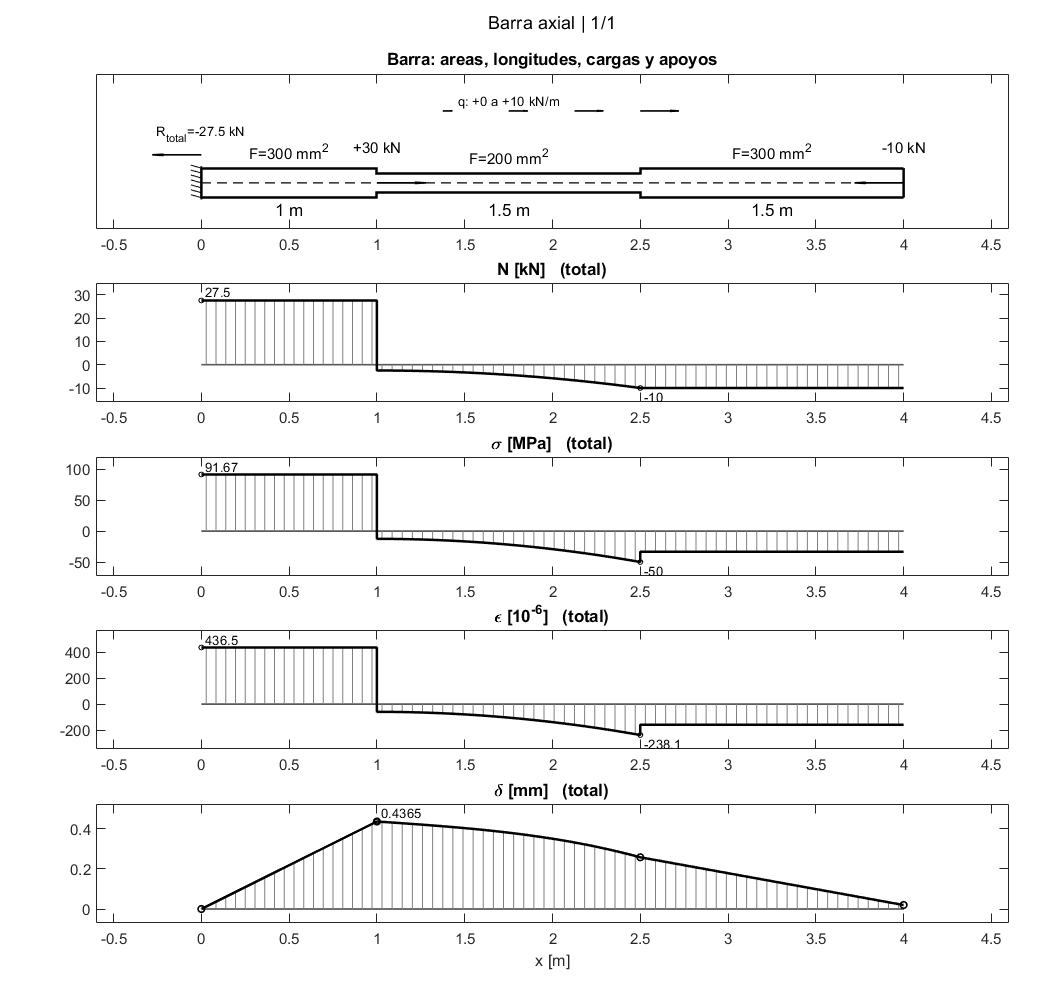

figuras = dibujarEpiuras(resultado);

dibujarEpiuras es una función local de representación; aquí elige la cantidad de diagramas y dibuja cada curva a partir de sus coeficientes. No necesitas editar sus bucles para cambiar de ejercicio.

## 11. Consultar una sección

Puedes consultar valores en una posición concreta. En una discontinuidad elige "derecha" o "izquierda" para distinguir los lados del corte. Esta consulta no cambia los datos ni el cálculo anterior.

posicionConsulta = x(1);
seccion = evaluarSeccion(resultado, posicionConsulta, "derecha");
disp(seccion);

          N: 2.7500e+04
      sigma: 9.1667e+07
    epsilon: 4.3651e-04
      delta: 0



evaluarSeccion evalúa la solución en una posición; aquí devuelve N, sigma, epsilon y delta en posicionConsulta, usando las unidades físicas de entrada.

## Alcance del cálculo

Barra recta y continua, elasticidad lineal y deformaciones pequeñas. F, E y alpha son constantes por tramo; q y deltaT pueden ser constantes o lineales por tramo. Se admiten apoyos con desplazamientos impuestos y topes contra un soporte fijo.

La entrada define un problema directo: dadas geometría, material y acciones, se obtienen esfuerzos y desplazamientos. No se incluyen búsqueda automática de dimensiones, plasticidad, pandeo ni contacto entre dos barras deformables.

## Funciones de apoyo

Estas funciones son locales y forman parte de este mismo archivo. Reúnen validaciones, resolución de apoyos, búsqueda de extremos y dibujo. No contienen ejercicios preseleccionados ni requieren otros archivos. Las fórmulas principales están desarrolladas en las secciones anteriores.

function m = preparar(d)
assert(isstruct(d) && isscalar(d), 'Axial:Datos', 'modelo debe ser una estructura.');
permitidos = {'nombre','nota','x','F','E','alpha','deltaT','puntuales', ...
    'distribuidas','apoyos','topes','referencias','opciones','resistencia'};
assert(all(ismember(fieldnames(d), permitidos)), 'Axial:Campo', ...
    'Hay un campo desconocido en los datos de entrada.');
for campo = {'x','F','E'}
    assert(isfield(d,campo{1}), 'Axial:Datos', 'Falta modelo.%s.',campo{1});
end
assert(isnumeric(d.x) && isvector(d.x), 'Axial:Geometria', 'x debe ser un vector numerico.');
x = double(d.x(:));
assert(numel(x)>=2 && isreal(x) && all(isfinite(x)) && all(diff(x)>0), ...
    'Axial:Geometria', 'x debe contener posiciones reales crecientes.');
ng = numel(x)-1;
F = vector(d.F, ng, 'F', true);
E = vector(d.E, ng, 'E', true);
alpha = vector(valor(d,'alpha',0), ng, 'alpha', false);
T = valor(d,'deltaT',zeros(ng,2));
if isscalar(T)
    T = repmat(T,ng,2);
elseif isvector(T) && numel(T)==ng && ~isequal(size(T),[ng 2])
    T = repmat(T(:),1,2);
end
assert(isnumeric(T) && isreal(T) && isequal(size(T),[ng 2]) && all(isfinite(T(:))), ...
    'Axial:Temperatura', 'deltaT: escalar, un valor por tramo o matriz [nTramos x 2].');
P = matriz(valor(d,'puntuales',zeros(0,2)),2,'puntuales');
Q = matriz(valor(d,'distribuidas',zeros(0,4)),4,'distribuidas');
A = matriz(valor(d,'apoyos',[x(1) 0]),2,'apoyos');
C = matriz(valor(d,'topes',zeros(0,3)),3,'topes');
assert(~isempty(A), 'Axial:Apoyos', 'Se necesita al menos un apoyo bilateral.');
assert(numel(unique(A(:,1)))==size(A,1), 'Axial:Apoyos', 'No repitas apoyos en una posicion.');
assert(size(C,1)<=8 && numel(unique(C(:,1)))==size(C,1), 'Axial:Topes', ...
    'Se admiten hasta 8 topes, uno por posicion.');
assert(all(abs(C(:,3))==1), 'Axial:Topes', 'El sentido del tope debe ser +1 o -1.');
assert(~any(ismember(C(:,1),A(:,1))), 'Axial:Topes', 'Un nodo no puede ser apoyo y tope a la vez.');
assert(all(Q(:,2)>Q(:,1)), 'Axial:Carga', 'Cada distribuida necesita xFinal > xInicial.');
posiciones = [P(:,1); Q(:,1); Q(:,2); A(:,1); C(:,1)];
assert(all(posiciones>=x(1) & posiciones<=x(end)), 'Axial:Rango', ...
    'Hay una carga, apoyo o tope fuera de la barra.');
xn = unique([x; posiciones]);
assert(all(diff(xn)>1e-12*(x(end)-x(1))), 'Axial:Geometria', ...
    'Existen posiciones casi coincidentes: unificalas en Datos.');
n = numel(xn)-1;
m = struct('nombre',string(valor(d,'nombre','Barra axial')), ...
    'nota',string(valor(d,'nota','')), 'x',xn, 'F',zeros(n,1), ...
    'E',zeros(n,1),'alpha',zeros(n,1),'deltaT',zeros(n,2), ...
    'q',zeros(n,2),'P',zeros(n+1,1),'apoyos',A,'topes',C);
m.original = d;
m.indiceOriginal = zeros(n,1);
for i=1:n
    centro = (xn(i)+xn(i+1))/2;
    g = find(x<=centro,1,'last');
    m.indiceOriginal(i)=g;
    m.F(i)=F(g); m.E(i)=E(g); m.alpha(i)=alpha(g);
    fraccion = ([xn(i),xn(i+1)]-x(g))/(x(g+1)-x(g));
    m.deltaT(i,:) = T(g,1)+(T(g,2)-T(g,1))*fraccion;
    for j=1:size(Q,1)
        if centro>Q(j,1) && centro<Q(j,2)
            f = ([xn(i),xn(i+1)]-Q(j,1))/(Q(j,2)-Q(j,1));
            m.q(i,:) = m.q(i,:)+Q(j,3)+(Q(j,4)-Q(j,3))*f;
        end
    end
end
for j=1:size(P,1)
    k=find(xn==P(j,1),1); m.P(k)=m.P(k)+P(j,2);
end
ref = valor(d,'referencias',struct);
m.referencias = struct('a',valor(ref,'a',1),'P',valor(ref,'P',1), ...
    'F',valor(ref,'F',1),'E',valor(ref,'E',1));
rv=[m.referencias.a m.referencias.P m.referencias.F m.referencias.E];
assert(isnumeric(rv) && isreal(rv) && numel(rv)==4 && all(isfinite(rv)&rv>0), ...
    'Axial:Referencias', 'Las referencias a, P, F y E deben ser escalares positivos.');
op = valor(d,'opciones',struct);
m.opciones = struct('desglose',string(valor(op,'desglose','auto')), ...
    'normalizar',valor(op,'normalizar',false),'rayado',valor(op,'rayado',true), ...
    'visible',char(valor(op,'visible','on')));
assert(ismember(m.opciones.desglose,["auto","total","completo"]), ...
    'Axial:Opciones','desglose debe ser auto, total o completo.');
assert(ismember(string(m.opciones.visible),["on","off"]), 'Axial:Opciones','visible: on u off.');
for k={'normalizar','rayado'}
    v=m.opciones.(k{1});
    assert(isscalar(v) && (islogical(v) || (isnumeric(v) && ismember(v,[0 1]))), ...
        'Axial:Opciones','normalizar y rayado deben ser true o false.');
end
res = valor(d,'resistencia',struct);
lt=vectorLimite(valor(res,'limiteTraccion',Inf),ng);
lc=vectorLimite(valor(res,'limiteCompresion',Inf),ng);
m.resistencia = struct('limiteTraccion',lt(m.indiceOriginal), ...
    'limiteCompresion',lc(m.indiceOriginal),'nMin',valor(res,'nMin',1));
assert(isnumeric(m.resistencia.nMin) && isscalar(m.resistencia.nMin) ...
    && isfinite(m.resistencia.nMin) && m.resistencia.nMin>0, ...
    'Axial:Resistencia','nMin debe ser positivo.');
end

function [r,K,f] = calcular(m)
n = numel(m.x); K=sparse(n,n); f=m.P;
for i=1:n-1
    L=m.x(i+1)-m.x(i); EA=m.E(i)*m.F(i); ix=[i i+1];
    K(ix,ix)=K(ix,ix)+(EA/L)*[1 -1;-1 1];
    fq=L/6*[2*m.q(i,1)+m.q(i,2);m.q(i,1)+2*m.q(i,2)];
    ft=EA*m.alpha(i)*mean(m.deltaT(i,:))*[-1;1];
    f(ix)=f(ix)+fq+ft;
end
[~,ia]=ismember(m.apoyos(:,1),m.x);
[~,ic]=ismember(m.topes(:,1),m.x);
nc=numel(ic); valido=false;
for estado=0:2^nc-1
    if nc==0, activos=false(0,1); else, activos=logical(bitget(estado,1:nc)).'; end
    fijos=[ia;ic(activos)]; valores=[m.apoyos(:,2);m.topes(activos,2)];
    libres=setdiff((1:n).',fijos); u=zeros(n,1); u(fijos)=valores;
    if ~isempty(libres)
        A=K(libres,libres); b=f(libres)-K(libres,fijos)*valores;
        s=1./sqrt(diag(A)); As=spdiags(s,0,numel(s),numel(s));
        u(libres)=s.*((As*A*As)\(s.*b));
    end
    R=K*u-f;
    escalaF=max([norm(f,1),norm(K*u,1),realmin]);
    tolF=1e-8*escalaF;
    escalaU=max([norm(u,inf),norm(valores,inf),norm(f,inf)/max(diag(K)),realmin]);
    tolU=1e-8*escalaU;
    penetracion=m.topes(:,3).*(u(ic)-m.topes(:,2));
    reaccionProhibida=m.topes(:,3).*R(ic);
    if all(penetracion<=tolU) && all(reaccionProhibida(activos)<=tolF)
        valido=true; break
    end
end
assert(valido,'Axial:Contacto','No se encontro un estado de contacto compatible.');
r=struct('u',u,'R',R,'contactosActivos',activos);
prototipo=struct('x0',0,'L',0,'N',zeros(1,3),'sigma',zeros(1,3), ...
    'epsilon',zeros(1,3),'delta',zeros(1,4),'q',zeros(1,2),'deltaT',zeros(1,2));
r.tramos=repmat(prototipo,n-1,1);
for i=1:n-1
    L=m.x(i+1)-m.x(i); EA=m.E(i)*m.F(i);
    q0=m.q(i,1); mq=(m.q(i,2)-q0)/L;
    T0=m.deltaT(i,1); mT=(m.deltaT(i,2)-T0)/L;
    N0=EA*((u(i+1)-u(i))/L-m.alpha(i)*mean(m.deltaT(i,:))) ...
        + L*(2*q0+m.q(i,2))/6;
    polN=[-mq/2 -q0 N0]; polS=polN/m.F(i);
    polE=polN/EA+[0 m.alpha(i)*mT m.alpha(i)*T0];
    polU=[polE(1)/3 polE(2)/2 polE(3) u(i)];
    r.tramos(i)=struct('x0',m.x(i),'L',L,'N',polN,'sigma',polS, ...
        'epsilon',polE,'delta',polU,'q',[mq q0],'deltaT',[mT T0]);
end
filas=cell(4,1); campos={'N','sigma','epsilon','delta'};
for k=1:4
    xmin=NaN; xmax=NaN; vmin=Inf; vmax=-Inf;
    for i=1:n-1
        t=r.tramos(i); s=puntosCriticos(t.(campos{k}),t.L);
        v=polyval(t.(campos{k}),s);
        [lo,j]=min(v); if lo<vmin, vmin=lo; xmin=t.x0+s(j); end
        [hi,j]=max(v); if hi>vmax, vmax=hi; xmax=t.x0+s(j); end
    end
    filas{k}={string(campos{k}),vmin,xmin,vmax,xmax};
end
r.extremos=cell2table(vertcat(filas{:}), ...
    'VariableNames',{'Magnitud','Minimo','xMinimo','Maximo','xMaximo'});
end

function v = comprobar(r,m,K,f)
escala=max([norm(f,1),norm(K*r.u,1),realmin]);
tol=1e-8*escala;
qTotal=sum(diff(m.x).*mean(m.q,2));
errorGlobal=abs(sum(m.P)+qTotal+sum(r.R));
errorSalto=0; errorCompatibilidad=0;
for i=1:numel(r.tramos)
    t=r.tramos(i);
    errorCompatibilidad=max(errorCompatibilidad,abs(polyval(t.delta,t.L)-r.u(i+1)));
    if i<numel(r.tramos)
        salto=polyval(r.tramos(i+1).N,0)-polyval(t.N,t.L)+m.P(i+1)+r.R(i+1);
        errorSalto=max(errorSalto,abs(salto));
    end
end
uEscala=max([norm(r.u,inf),norm(f,inf)/max(diag(K)),realmin]);
[~,ap]=ismember(m.apoyos(:,1),m.x);
errorApoyo=max(abs(r.u(ap)-m.apoyos(:,2)));
fijos=ap; if ~isempty(m.topes)
    [~,ic]=ismember(m.topes(:,1),m.x); fijos=[fijos;ic(r.contactosActivos)];
end
libres=setdiff((1:numel(m.x)).',fijos);
errorLibres=norm(r.R(libres),inf); if isempty(errorLibres), errorLibres=0; end
errorExtremos=max(abs([polyval(r.tramos(1).N,0)+m.P(1)+r.R(1), ...
    polyval(r.tramos(end).N,r.tramos(end).L)-m.P(end)-r.R(end)]));
assert(max([errorGlobal,errorSalto,errorLibres,errorExtremos])<=tol, ...
    'Axial:Equilibrio','No se supera la comprobacion de equilibrio.');
assert(max(errorCompatibilidad,errorApoyo)<=1e-8*uEscala, ...
    'Axial:Compatibilidad','No se supera la comprobacion de desplazamientos.');
v=struct('superadas',true,'errorEquilibrio',errorGlobal,'errorSaltos',errorSalto, ...
    'errorExtremos',errorExtremos,'errorNodosLibres',errorLibres, ...
    'errorCompatibilidad',errorCompatibilidad,'errorApoyos',errorApoyo);
end

function v=resistencia(r,m)
n=Inf; sT=0; sC=0;
for i=1:numel(r.tramos)
    t=r.tramos(i); s=puntosCriticos(t.sigma,t.L); valores=polyval(t.sigma,s);
    tr=max([0 valores]); co=max([0 -valores]); sT=max(sT,tr); sC=max(sC,co);
    if tr>0, n=min(n,m.resistencia.limiteTraccion(i)/tr); end
    if co>0, n=min(n,m.resistencia.limiteCompresion(i)/co); end
end
definida=any(isfinite(m.resistencia.limiteTraccion) | isfinite(m.resistencia.limiteCompresion));
v=struct('evaluada',definida,'sigmaTraccionMax',sT,'sigmaCompresionMax',sC, ...
    'factorSeguridad',n,'nMin',m.resistencia.nMin,'cumple',n>=m.resistencia.nMin);
end

function s=puntosCriticos(p,L)
d=polyder(p); primero=find(d~=0,1);
if isempty(primero), d=[]; else, d=d(primero:end); end
if isempty(d), z=[]; else, z=roots(d); end
z=real(z(abs(imag(z))<1e-9*max(1,L)));
s=unique([0;L;z(z>0 & z<L)]).';
end
function v=valor(s,c,predeterminado)
if isfield(s,c), v=s.(c); else, v=predeterminado; end
end
function a=matriz(a,n,nombre)
if isempty(a), a=zeros(0,n); end
assert(isnumeric(a) && isreal(a) && ismatrix(a) && size(a,2)==n && all(isfinite(a(:))), ...
    'Axial:Datos','%s necesita %d columnas numericas finitas.',nombre,n);
a=double(a);
end
function a=vector(a,n,nombre,positivo)
assert(isnumeric(a) && isreal(a) && isvector(a) && all(isfinite(a(:))), ...
    'Axial:Datos','%s debe ser un vector numerico finito.',nombre);
if isscalar(a), a=repmat(a,n,1); end
a=double(a(:));
assert(numel(a)==n,'Axial:Datos','%s necesita un valor por tramo original.',nombre);
if positivo, assert(all(a>0),'Axial:Datos','%s debe ser positivo.',nombre); end
end
function a=vectorLimite(a,n)
assert(isnumeric(a) && isreal(a) && isvector(a) && all(a(:)>0), ...
    'Axial:Resistencia','Los limites deben ser positivos, o Inf si no se comprueban.');
if isscalar(a), a=repmat(a,n,1); end
a=a(:); assert(numel(a)==n,'Axial:Resistencia','Se necesita un limite por tramo original.');
end

function [u,R,activos] = resolverApoyos(m,K,f)
n=numel(m.x);
[~,ia]=ismember(m.apoyos(:,1),m.x);
[~,ic]=ismember(m.topes(:,1),m.x);
nc=numel(ic); valido=false;
for estado=0:2^nc-1
    if nc==0, activos=false(0,1); else, activos=logical(bitget(estado,1:nc)).'; end
    fijos=[ia;ic(activos)]; valores=[m.apoyos(:,2);m.topes(activos,2)];
    libres=setdiff((1:n).',fijos); u=zeros(n,1); u(fijos)=valores;
    if ~isempty(libres)
        A=K(libres,libres); b=f(libres)-K(libres,fijos)*valores;
        s=1./sqrt(diag(A)); As=spdiags(s,0,numel(s),numel(s));
        u(libres)=s.*((As*A*As)\(s.*b));
    end
    R=K*u-f;
    escalaF=max([norm(f,1),norm(K*u,1),realmin]);
    tolF=1e-8*escalaF;
    escalaU=max([norm(u,inf),norm(valores,inf),norm(f,inf)/max(diag(K)),realmin]);
    tolU=1e-8*escalaU;
    penetracion=m.topes(:,3).*(u(ic)-m.topes(:,2));
    reaccionProhibida=m.topes(:,3).*R(ic);
    if all(penetracion<=tolU) && all(reaccionProhibida(activos)<=tolF)
        valido=true; break
    end
end
assert(valido,'Axial:Contacto','No se encontro un estado de contacto compatible.');

end

function tablaExtremos = obtenerExtremos(r)
n=numel(r.tramos)+1;
filas=cell(4,1); campos={'N','sigma','epsilon','delta'};
for k=1:4
    xmin=NaN; xmax=NaN; vmin=Inf; vmax=-Inf;
    for i=1:n-1
        t=r.tramos(i); s=puntosCriticos(t.(campos{k}),t.L);
        v=polyval(t.(campos{k}),s);
        [lo,j]=min(v); if lo<vmin, vmin=lo; xmin=t.x0+s(j); end
        [hi,j]=max(v); if hi>vmax, vmax=hi; xmax=t.x0+s(j); end
    end
    filas{k}={string(campos{k}),vmin,xmin,vmax,xmax};
end
tablaExtremos=cell2table(vertcat(filas{:}), ...
    'VariableNames',{'Magnitud','Minimo','xMinimo','Maximo','xMaximo'});
end

function figuras = dibujarEpiuras(r)
m=r.modelo; ref=m.referencias;
base=[1000 1e6 1e-6 1e-3]; etiquetas={'N [kN]','\sigma [MPa]','\epsilon [10^{-6}]','\delta [mm]'};
termica=base; etiquetasT=etiquetas;
if m.opciones.normalizar
    base=[ref.P, ref.P/ref.F, ref.P/(ref.E*ref.F), ref.P*ref.a/(ref.E*ref.F)];
    etiquetas={'N / P','\sigma / (P/F)','\epsilon / (P/(EF))','\delta / (Pa/(EF))'};
    et=max(abs(m.alpha.*m.deltaT),[],'all');
    if et>0
        termica=[et*ref.E*ref.F,et*ref.E,et,et*ref.a];
        etiquetasT={'N / (\epsilon_T EF)','\sigma / (\epsilon_T E)', ...
            '\epsilon / \epsilon_T','\delta / (\epsilon_T a)'};
    end
end
series=struct('r',{},'campo',{},'escala',{},'titulo',{});
desglose=isfield(r.componentes,'mecanica') && m.opciones.desglose~="total";
if desglose
    for k=1:4, agregar(r.componentes.mecanica,k,base(k),etiquetas{k},'p'); end
    for k=1:3, agregar(r.componentes.termica,k,termica(k),etiquetasT{k},'t'); end
    if m.opciones.desglose=="completo"
        agregar(r.componentes.termica,4,termica(4),etiquetasT{4},'t');
        for k=1:4, agregar(r,k,base(k),etiquetas{k},'total'); end
    else
        agregar(r,2,base(2),etiquetas{2},'total');
    end
else
    for k=1:4, agregar(r,k,base(k),etiquetas{k},'total'); end
end
porPagina=5; nPaginas=ceil(numel(series)/porPagina);
figuras=gobjects(nPaginas,1);
for pagina=1:nPaginas
    indices=(pagina-1)*porPagina+1:min(pagina*porPagina,numel(series));
    figuras(pagina)=figure('Color','w','Visible',m.opciones.visible, ...
        'Name',char(m.nombre+" - "+pagina+"/"+nPaginas), ...
        'Position',[80+25*(pagina-1) 45 850 190+150*numel(indices)]);
    annotation(figuras(pagina),'textbox',[.09 .96 .86 .035], ...
        'String',char(m.nombre+" | "+pagina+"/"+nPaginas),'Interpreter','none', ...
        'EdgeColor','none','HorizontalAlignment','center','FontSize',11);
    pesos=[1.3 ones(1,numel(indices))]; separacion=.055;
    alturas=(.86-separacion*numel(indices))*pesos/sum(pesos);
    borde=.925; ejes=gobjects(numel(pesos),1);
    for j=1:numel(pesos)
        borde=borde-alturas(j);
        ejes(j)=axes(figuras(pagina),'Position',[.09 borde .86 alturas(j)],'FontSize',9);
        borde=borde-separacion;
    end
    esquema(ejes(1),r);
    for j=1:numel(indices)
        curva(ejes(j+1),series(indices(j)),m);
    end
    etiquetaX='x [m]'; if m.opciones.normalizar, etiquetaX='x/a'; end
    xlabel(ejes(end),etiquetaX);
    drawnow;
end

    function agregar(sol,k,escala,etiqueta,sufijo)
        campos={'N','sigma','epsilon','delta'};
        series(end+1)=struct('r',sol,'campo',campos{k},'escala',escala, ...
            'titulo',[etiqueta '   (' sufijo ')']);
    end
end

function esquema(ax,r)
m=r.modelo; hold(ax,'on'); L=m.x(end)-m.x(1);
sx=1; if m.opciones.normalizar, sx=m.referencias.a; end
xx=m.x/sx; margen=0.15*L/sx;
h=0.4*m.F/max(m.F);
stairs(ax,xx,[h;h(end)],'k-','LineWidth',1.5);
stairs(ax,xx,-[h;h(end)],'k-','LineWidth',1.5);
plot(ax,[xx(1) xx(1)],[-h(1) h(1)],'k-','LineWidth',1.5);
plot(ax,[xx(end) xx(end)],[-h(end) h(end)],'k-','LineWidth',1.5);
plot(ax,[xx(1) xx(end)],[0 0],'k--','LineWidth',0.8);
for i=1:numel(h)
    centro=mean(xx(i:i+1));
    if m.opciones.normalizar
        area=mult(m.F(i)/m.referencias.F,'F');
        long=mult((m.x(i+1)-m.x(i))/sx,'a');
    else
        area=sprintf('F=%.3g mm^2',m.F(i)*1e6);
        long=sprintf('%.3g m',m.x(i+1)-m.x(i));
    end
    text(ax,centro,h(i)+0.13,area,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',9);
    text(ax,centro,-0.72,long,'HorizontalAlignment','center','FontSize',10);
    if any(m.alpha(i)*m.deltaT(i,:)~=0)
        patch(ax,xx([i i+1 i+1 i]),[-h(i) -h(i) h(i) h(i)], ...
            [1 0.65 0.3],'FaceAlpha',0.15,'EdgeColor','none');
    end
end
escalaP=1000; unidad=' kN';
if m.opciones.normalizar, escalaP=m.referencias.P; unidad='P'; end
for j=1:numel(m.P)
    if m.P(j)~=0
        flecha(ax,xx(j),0,sign(m.P(j))*0.07*L/sx);
        text(ax,xx(j),0.98,sprintf('%+.3g%s',m.P(j)/escalaP,unidad), ...
            'HorizontalAlignment','center','FontSize',9);
    end
end
ap=m.apoyos(:,1);
for j=1:size(m.topes,1)
    [~,i]=min(abs(m.x-m.topes(j,1)));
    pared(ax,m.topes(j,1)/sx,m.topes(j,3),0.035*L/sx);
    if r.contactosActivos(j), estado='cerrado'; ap=[ap;m.topes(j,1)];
    else, estado='abierto'; end
    text(ax,m.topes(j,1)/sx,-1.03,sprintf('tope %s; \\Delta=%.3g m', ...
        estado,abs(m.topes(j,2))),'HorizontalAlignment','center','FontSize',8);
    if ~r.contactosActivos(j), text(ax,xx(i),0.95,'R=0','FontSize',8); end
end
for j=1:size(m.apoyos,1)
    sentido=-1; if m.apoyos(j,1)==m.x(end), sentido=1; end
    pared(ax,m.apoyos(j,1)/sx,sentido,0);
    if m.apoyos(j,2)~=0
        text(ax,m.apoyos(j,1)/sx,-1.03,sprintf('\\delta=%.3g m',m.apoyos(j,2)), ...
            'HorizontalAlignment','center','FontSize',8);
    end
end
for j=1:numel(ap)
    i=find(m.x==ap(j),1);
    if abs(r.R(i))>1e-10*max([abs(r.R);realmin])
        flecha(ax,xx(i),0.76,sign(r.R(i))*0.07*L/sx);
        text(ax,xx(i),1.35,sprintf('R_{total}=%+.3g%s',r.R(i)/escalaP,unidad), ...
            'HorizontalAlignment','center','FontSize',8);
    end
end
qmax=max(abs(m.q),[],'all');
if qmax>0
    for i=1:numel(h)
        if ~any(m.q(i,:)~=0), continue; end
        pos=linspace(xx(i),xx(i+1),5);
        valores=linspace(m.q(i,1),m.q(i,2),5);
        for j=1:5
            flecha(ax,pos(j),1.95,0.055*L/sx*valores(j)/qmax);
        end
        if m.opciones.normalizar
            qlabel=sprintf('q: %+.3g a %+.3g P/a',m.q(i,:)*sx/escalaP);
        else
            qlabel=sprintf('q: %+.3g a %+.3g kN/m',m.q(i,:)/1000);
        end
        text(ax,mean(xx(i:i+1)),2.25,qlabel,'HorizontalAlignment','center','FontSize',8);
    end
end
if r.hayTemperatura
    text(ax,mean([xx(1) xx(end)]),2.65,'Sombreado: tramo con deformacion termica', ...
        'HorizontalAlignment','center','FontSize',8);
end
xlim(ax,[xx(1)-margen xx(end)+margen]); ylim(ax,[-1.25 2.95]);
set(ax,'YTick',[],'Box','on');
title(ax,'Barra: areas, longitudes, cargas y apoyos','Units','normalized', ...
    'Position',[.5 1.03 0],'FontSize',10);
end

function curva(ax,s,m)
hold(ax,'on'); sx=1; if m.opciones.normalizar, sx=m.referencias.a; end
L=m.x(end)-m.x(1); margen=0.15*L/sx;
plot(ax,[m.x(1) m.x(end)]/sx,[0 0],'-','Color',[.35 .35 .35],'LineWidth',1);
vx=[]; vy=[];
for i=1:numel(s.r.tramos)
    t=s.r.tramos(i); p=t.(s.campo);
    dp=polyder(p); k=find(dp~=0,1);
    if isempty(k), z=[]; else, z=roots(dp(k:end)); end
    z=real(z(abs(imag(z))<1e-9*max(1,t.L))); z=z(z>0 & z<t.L);
    a=unique([linspace(0,t.L,81).';z(:)]);
    v=polyval(p,a)/s.escala;
    vx=[vx;(t.x0+a)/sx]; vy=[vy;v];
    if m.opciones.rayado
        count=max(4,round(70*t.L/L)); paso=t.L/count;
        a=((0:count-1)+.5)*paso; v=polyval(p,a)/s.escala;
        plot(ax,[(t.x0+a)/sx;(t.x0+a)/sx],[zeros(size(v));v], ...
            '-','Color',[.5 .5 .5],'LineWidth',.5);
    end
end
plot(ax,vx,vy,'k-','LineWidth',1.5);
lo=min([0;vy]); hi=max([0;vy]); rango=hi-lo;
if rango==0, rango=1; end
ylim(ax,[lo-.16*rango hi+.20*rango]);
xlim(ax,[m.x(1)/sx-margen m.x(end)/sx+margen]);
title(ax,s.titulo,'Interpreter','tex','Units','normalized','Position',[.5 1.03 0],'FontSize',10);
set(ax,'Box','on');
if s.campo=="delta"
    plot(ax,m.x/sx,s.r.u/s.escala,'ko','MarkerSize',4,'LineWidth',1);
end
k=find(s.r.extremos.Magnitud==string(s.campo),1); e=s.r.extremos(k,:);
pares=[e.xMinimo e.Minimo;e.xMaximo e.Maximo];
if abs(e.Maximo-e.Minimo)<1e-10*max([abs(e.Maximo),abs(e.Minimo),realmin]), pares=pares(1,:); end
for par=pares.'
    if abs(par(2)/s.escala)>1e-12*max([abs(vy);realmin])
        plot(ax,par(1)/sx,par(2)/s.escala,'ko','MarkerSize',3);
        alineacion='bottom'; if par(2)<0, alineacion='top'; end
        horizontal='left'; if par(1)>m.x(end)-.05*L, horizontal='right'; end
        text(ax,par(1)/sx,par(2)/s.escala,sprintf(' %.4g ',par(2)/s.escala), ...
            'VerticalAlignment',alineacion,'HorizontalAlignment',horizontal, ...
            'FontSize',8,'Clipping','on');
    end
end
end
function flecha(ax,x,y,dx)
if dx~=0, quiver(ax,x,y,dx,0,0,'k','LineWidth',1,'MaxHeadSize',.7); end
end
function pared(ax,x,sentido,separacion)
x=x+sentido*separacion;
line(ax,[x x],[-.45 .45],'Color','k','LineWidth',1.1);
w=diff(xlim(ax))*.015;
for y=linspace(-.4,.4,7)
    plot(ax,[x x+sentido*w],[y y+.08],'k-','LineWidth',.6);
end
end
function t=mult(v,simbolo)
if abs(v-1)<1e-10, t=simbolo; else, t=sprintf('%.3g%s',v,simbolo); end
end

function v = evaluarSeccion(r, x, lado)
if nargin<3, lado="derecha"; end
assert(ismember(string(lado),["derecha","izquierda"]), ...
    'Axial:Consulta','lado debe ser derecha o izquierda.');
forma=size(x); x=x(:);
limites=[r.tramos.x0]; final=r.tramos(end).x0+r.tramos(end).L;
assert(isnumeric(x) && isreal(x) && all(isfinite(x)) ...
    && all(x>=limites(1) & x<=final),'Axial:Consulta','Consulta fuera de la barra.');
campos={'N','sigma','epsilon','delta'};
for k=1:4, v.(campos{k})=zeros(size(x)); end
for j=1:numel(x)
    if string(lado)=="izquierda"
        i=find(limites<x(j),1,'last'); if isempty(i), i=1; end
    else
        i=find(limites<=x(j),1,'last');
    end
    t=r.tramos(i); s=x(j)-t.x0;
    for k=1:4, v.(campos{k})(j)=polyval(t.(campos{k}),s); end
end
for k=1:4, v.(campos{k})=reshape(v.(campos{k}),forma); end
end